# Performance of Various Symmetric Matrix-Vector Multiplication Routines

This Live Script helps you visualize the performance of the various symmetric matrix-vector multiplication routines (SymMatVec1, SymMatVec2, and SymMatVec3).

After you implement SymMatVec3.c, execute 'make test' in directory LAFFPfC -> Assignements -> Week1 -> C.  This creates output file 'output.m' with timing data.  This Life Script then creates graphs from that timing data.

## Step 1: Load timing data

output

## Step 2: Plot the timing data.

The first graph shows the execution time of the different implementations as a function of the matrix size $n$.

close all

plot( data_SymMatVec1( :,1 ), data_SymMatVec1( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

plot( data_SymMatVec2( :,1 ), data_SymMatVec2( :, 2 ), 'b-.o' ); 
plot( data_SymMatVec3( :,1 ), data_SymMatVec3( :, 2 ), 'r--*' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n' );
ylabel( 'Time (in sec.)' );
legend( 'SymMatVec1', ...
        'SymMatVec2', ...
        'SymMatVec3', 'Location', 'NorthWest' );

Print the resulting graph to file 'SymMatVecTime.pdf'.

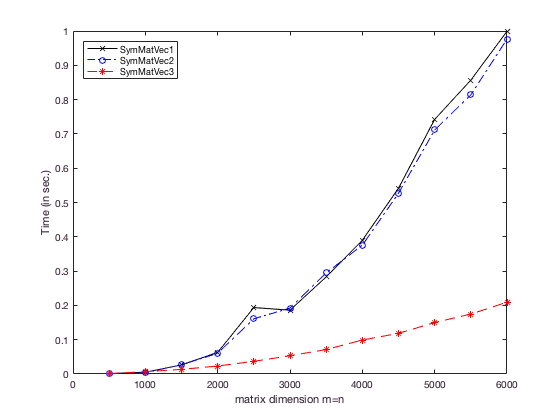

 print('SymMatVecTime', '-dpdf')

Notice that SymMatVec3 is considerably faster than the other implementations.  We illustrate that by plotting the speedup of SymMatVec2 and SymMatVec3 relative to SymMatVec1.

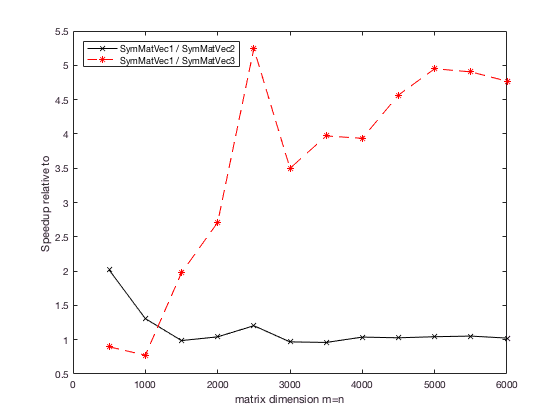

plot( data_SymMatVec1( :,1 ), data_SymMatVec1( :, 2 ) ./ data_SymMatVec2( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

plot( data_SymMatVec3( :,1 ), data_SymMatVec1( :, 2 ) ./ data_SymMatVec3( :, 2 ), 'r--*' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n' );
ylabel( 'Speedup relative to ' );
legend( 'SymMatVec1 / SymMatVec2', ...
        'SymMatVec1 / SymMatVec3', 'Location', 'NorthWest' );

## Step 3: Plot performance.

We often view the rate at which routines compute rather than the time required for completing the computation.

We know that a symmetric matrix-vector multiplication$ A x + y$ requires $2n^2$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^2}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^2}/{t} \times 10^{-9}$.

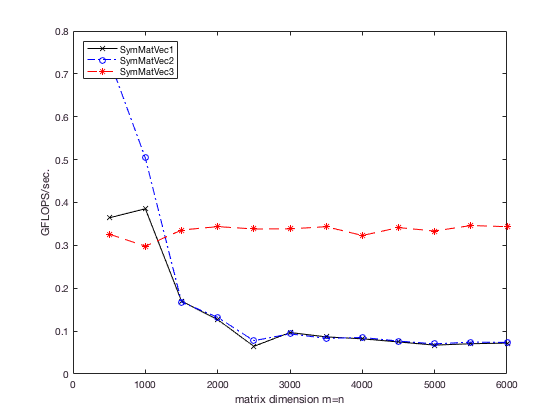

ns = data_SymMatVec1( :, 1 );                                   % Extract a vector of matrix size.
gflops = 2.0 * ns .* ns ./ data_SymMatVec1( :, 2 ) * 1.0e-9;    % Compute a vector of corresponding GFLOPS/sec from the timing data.
plot( ns, gflops, 'k-x' );                                      % Plot the performance data

hold on

ns = data_SymMatVec2( :, 1 );
gflops = 2.0 * ns .* ns ./ data_SymMatVec2( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'b-.o' ); 

ns = data_SymMatVec3( :, 1 );
gflops = 2.0 * ns .* ns ./ data_SymMatVec3( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'r--*' ); 

xlabel( 'matrix dimension m=n' );
ylabel( 'GFLOPS/sec.' );
legend( 'SymMatVec1', ...
        'SymMatVec2', ...
        'SymMatVec3', 'Location', 'NorthWest' );